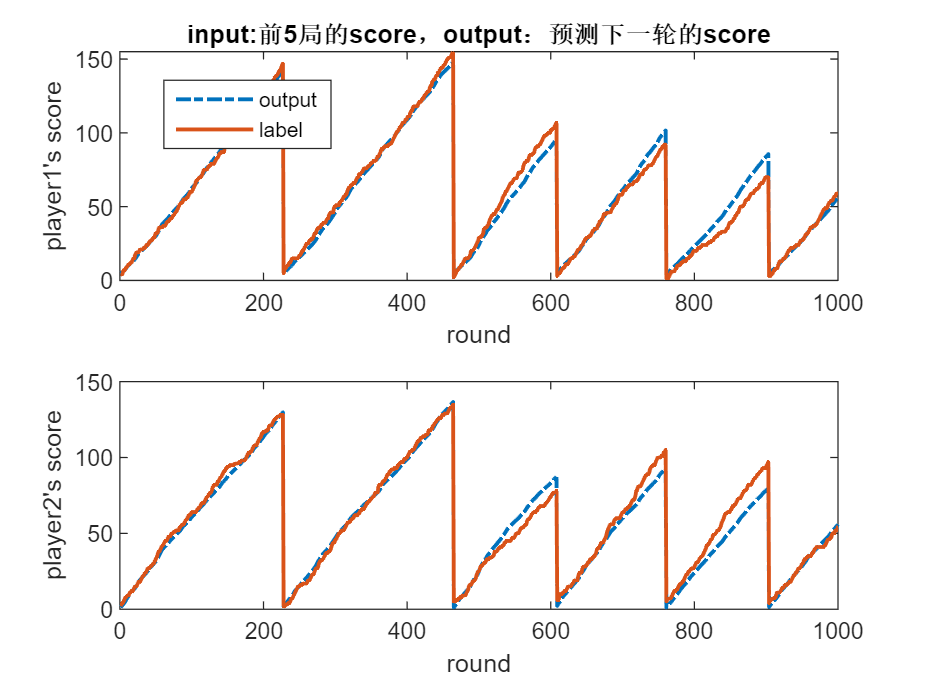

clc,clear
load test_out.mat
% out = round(reshape(test_out(:,1,:),1000,2));
out = reshape(test_out(:,1,:),1000,2);
label = reshape(test_labels(:,1,:),1000,2);
figure
subplot(2,1,1)
plot(out(:,1),'-.','LineWidth',1.5)
hold on
plot(label(:,1),'-','LineWidth',1.5)
legend('output','label')
legend("Position",[0.1784,0.78705,0.17772,0.096446])
ylabel("player1's score")
xlabel("round")
title("input:前5局的score，output：预测下一轮的score")
subplot(2,1,2)
plot(out(:,2),'-.','LineWidth',1.5)
hold on
plot(label(:,2),'-','LineWidth',1.5)
legend('output','label')
legend("Position",[0.1784,0.78705,0.17772,0.096446])
ylabel("player2's score")
xlabel("round")

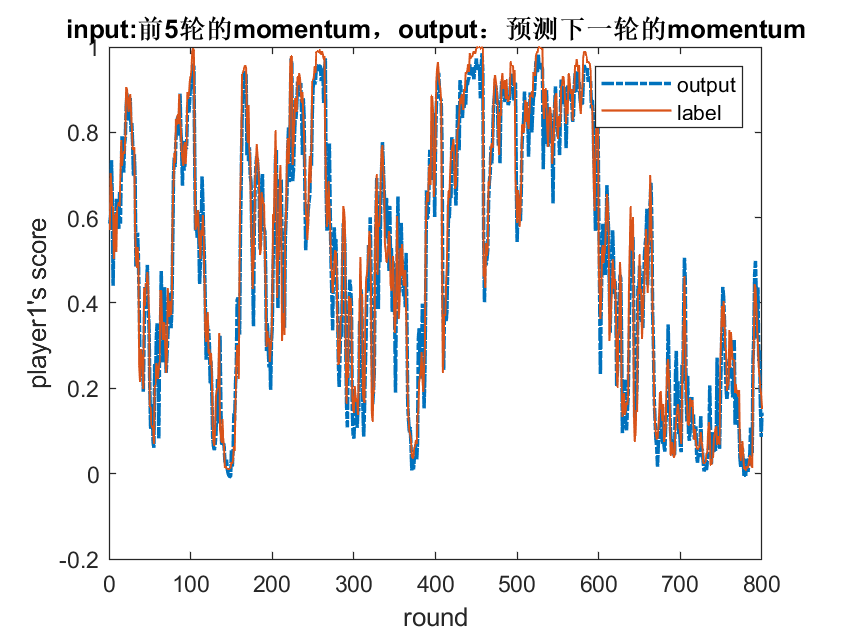

clc,clear
load test_out_m.mat
output_len = length(test_out(:,1,1));
out = reshape(test_out(:,1,:),output_len,2);
label = reshape(test_labels(:,1,:),output_len,2);
% index1 = find(abs(out(:, 1) - label(:, 1)) > 0.15);
figure
% subplot(2,1,1)
plot(out(:,1),'-.','LineWidth',1.5)
hold on
plot(label(:,1),'-','LineWidth',1)
% hold on
% plot(index1,out(index1,1),'*')
legend('output','label')
ylabel("player1's score")
xlabel("round")
title("input:前5轮的momentum，output：预测下一轮的momentum")
xlim([0,800])

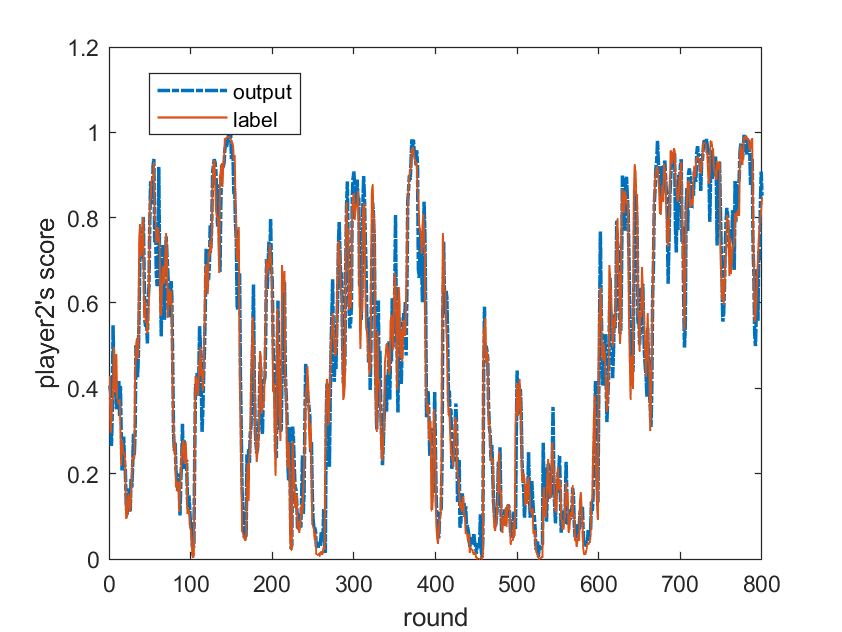

% subplot(2,1,2)
figure
plot(out(:,2),'-.','LineWidth',1.5)
hold on
plot(label(:,2),'-','LineWidth',1)
legend('output','label')
legend("Position",[0.1784,0.78705,0.17772,0.096446])
ylabel("player2's score")
xlabel("round")
xlim([0,800])

% figure
% plot(out(:,1)-label(:,1))
% index = find(abs(out(:, 1) - label(:, 1)) > 0.1);
% hold on
% plot(index,(out(index,1)-label(index,1)),'*')